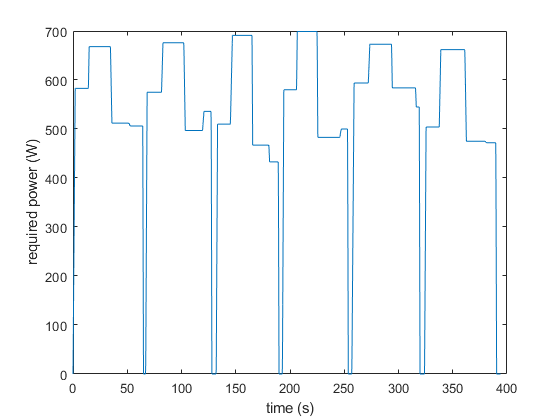

% titt = 'takeoff'
load load_descend
load fc_power_descend_dp
old_w = str2double(to_try.power)';
old_t = str2double(to_try.time)';
t = 0:1e-3:old_t(end);
w = fixpt_interp1(old_t,old_w,t,float('single'),[],float('single'),[],'Floor');
% w = awgn(w,50,'measured');
clear old_w old_t to_try
plot(t,w)
xlabel('time (s)');
ylabel('required power (W)');


Ts = 1; % Sample time
Pout = w(1:Ts/1e-3:t(end)/1e-3);
size_tot = 61-20;
size_arr = size(fc_power_array);
Index_for_arr = zeros(size_tot,size_arr(2))+(1:size_arr(2));
Input_1 = zeros(size_tot,size_arr(2))+Pout-140;
Input_2 = zeros(size_tot,length(Index_for_arr)) + linspace(90,70,length(Index_for_arr))-20;
for k=2:size_tot
    Input_2(k,:) = Input_2(k,:)-k;
end

test = zeros(size_tot,length(Index_for_arr));
for j=1:size_tot
    for i=1:length(Index_for_arr)
        test(j,i) = fc_power_array(round(Input_2(j,i)),Index_for_arr(j,i));
    end
end
Input_1 = Input_1';
Input_2 = Input_2';
test = test';

Input_1 = Input_1(:);
Input_2 = Input_2(:);
test = test(:);



data_to_anfis = [Input_1 ...
    Input_2 ...
    test];


# Data from DP

% size_tot = 61-20;
% Index_for_arr = zeros(size_tot,1170)+(1:1170);
% Input_1 = zeros(size_tot,1170)+w(1:1e3:end-1)-140;
% Input_2 = zeros(size_tot,length(Index_for_arr)) + linspace(90,70,length(Index_for_arr))-20;
% for k=2:size_tot
%     Input_2(k,:) = Input_2(k,:)-k;
% end
% 
% test = zeros(size_tot,length(Index_for_arr));
% for j=1:size_tot
%     for i=1:length(Index_for_arr)
%         test(j,i) = fc_power_array(round(Input_2(j,i)),Index_for_arr(j,i));
%     end
% end
% Input_1 = Input_1';
% Input_2 = Input_2';
% test = test';
% 
% Input_1 = Input_1(:);
% Input_2 = Input_2(:);
% test = test(:);
% 
% 
% 
% data_to_anfis = [Input_1 ...
%     Input_2 ...
%     test];


genOpt = genfisOptions('GridPartition');
genOpt.NumMembershipFunctions = [6 6];
genOpt.InputMembershipFunctionType = 'gaussmf';
genOpt.OutputMembershipFunctionType = 'linear';
inFIS = genfis(data_to_anfis(:,1:2),data_to_anfis(:,3),genOpt);

opt = anfisOptions('InitialFIS',inFIS,'EpochNumber',50);
opt.DisplayANFISInformation = 0;
opt.DisplayErrorValues = 0;
opt.DisplayStepSize = 0;
opt.DisplayFinalResults = 0;
tic
[fis,trainError] = anfis(data_to_anfis,opt);
toc

Elapsed time is 111.900095 seconds.


fisRMSE = min(trainError)

fisRMSE =   48.032384762513665


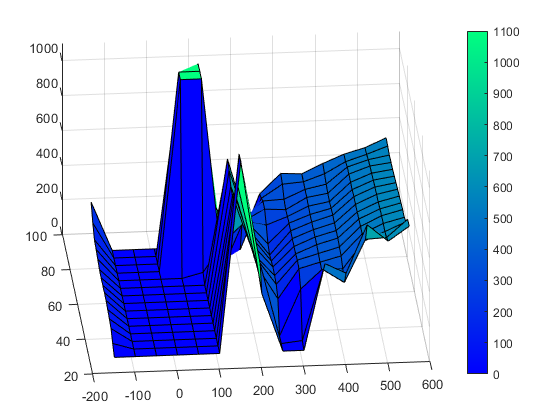

% writeFIS(fis,'DP_ANFIS_low')
writeFIS(fis,'DP_ANFIS_descend')
% writeFIS(fis,'DP_ANFIS_climb')
% writeFIS(fis,'DP_ANFIS_test')
[mx,my,mz] = gensurf(fis);
surf(mx,my+20,min(1100,max(0,mz)));
zlim([0 1100])
colorbar
colormap winter;

figure
anfisOutput = evalfis(fis,trainingData(:,1:2));
tt = 1:length(trainingData(:,3));
plot(tt,trainingData(:,3),'*r',tt,anfisOutput,'.b')
legend('Training Data','ANFIS Output','Location','NorthWest')